# staticな学習データをGPR

テストデータとも比較して，精度も確認する．

シンプルに解いて，オイラーの回転運動方程式を解いてlight curveを計算して，比較する．

csvの中身：

- xTrain: [q, satPos, obsPos, sunPos]

- yTrain: [mApp]

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/')));
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(strcat(curdir, '/../../gpryui/'));

tStart = tic;

### input values directly

% inputGP = "attitude"
% inputGP = "attitude, mApp_pastMean" % "attitude, mApp_pastMean" or "attitude, position, mApp_pastMean" or "attitude, relativePosition, mApp_pastMean"
% inputGP = "attitude, position, mApp_pastMean" % [q, r, obsECI, mApp_past]
inputGP = "attitude, relativePosition, mApp_pastMean"

inputGP = "attitude, relativePosition, mApp_pastMean"


predictionStep = 1; % 1:ode, 2: simpleGP as a prediction model
validData = "boxWing_lcAtti_onOrbit.mat"

validData = "boxWing_lcAtti_onOrbit.mat"


tau = log(1);
sigma = log(0.25);
eta = log(0.1);
params = [tau, sigma, eta]; % hyper parameters

tstep = 1;
% tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

tSpanPast = 20;

### read data

% read train data ------
datadir = strcat(curdir, '/../../data/static/');
cddir = datadir;
cd(cddir)
trainStruct = dir('*.csv');
trainDF = [];
for i = 1:1:size(trainStruct, 1)
    fName = trainStruct(i).name;
    df = readmatrix(fName); % [t_jd, mApp, q, r, obsECI, sunPosI, mApp_pastMean], nIniCon x 16
    trainDF = [trainDF; df];
end
cd(curdir)

% read valid data -----
valid = load(validData); % [t_, mApp, q, phi, theta, psi, w, sat, r, v, obsECI, sunPosI, jdHistory]

### data handling

% train data ------

outputDim = 1; % [mApp]
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    % inputDim = 11; % [q, r, obsECI, mApp_pastMean], nx11, sunPosI はほぼ動いてないとして入力に入れない
    x_train = trainDF(:,3:end);

    % 入力のorderを揃えたい
    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);

    % x_train_r = x_train_r ./ max(x_train_r, [], "all");
    % x_train_obsECI = x_train_obsECI ./ max(x_train_obsECI, [], "all");
    r_valid_max = max(valid.r, [], "all");
    obsECI_valid_max = max(valid.obsECI, [], "all");
    x_train_r = x_train_r ./ r_valid_max;
    x_train_obsECI = x_train_obsECI ./ obsECI_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_r, x_train_obsECI, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    x_train = trainDF(:,3:end);

    x_train_q = x_train(:,1:4);
    x_train_r = x_train(:,5:7);
    x_train_obsECI = x_train(:,8:10);
    x_train_obsToTarget = x_train_r - x_train_obsECI;
    x_train_sunPosI = x_train(:,11:13);
    x_train_mApp_pastMean = x_train(:,14);

    obsToTarget_valid_max = max(valid.r - valid.obsECI, [], "all"); % 相対位置の最大値を取得 for order調整
    x_train_obsToTarget = x_train_obsToTarget ./ obsToTarget_valid_max;

    % x_trainを決定k
    x_train = [x_train_q, x_train_obsToTarget, x_train_mApp_pastMean];
    inputDim = size(x_train, 2);

elseif strcmp(inputGP, "attitude, mApp_pastMean")
    % inputDim = 5; % [q, mApp_pastMean]
    x_train = [trainDF(:,3:6), trainDF(:,end)]; % [q, mApp_pastMean]
    inputDim = size(x_train, 2);
elseif strcmp(inputGP, "attitude")
    x_train = trainDF(:,3:6); % [q]
    inputDim = size(x_train, 2);
end
y_train = trainDF(:, 2); % [mApp]

size(x_train)

ans =        53928           8


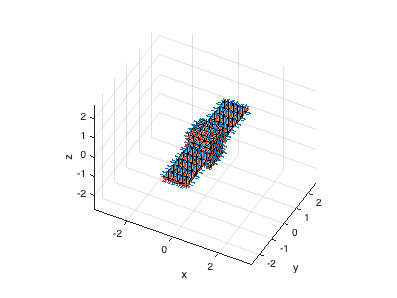


% light curve の inf を処理
y_train(isinf(y_train)) = NaN;
y_train = fillmissing(y_train, 'previous'); % mAppのinfを直前の値に置換
x_train(isinf(x_train)) = NaN;
x_train = fillmissing(x_train, 'previous'); % mApp_pastMeanの inf 処理
valid.mApp(isinf(valid.mApp)) = NaN;
valid.mApp = fillmissing(valid.mApp, 'previous'); % 真値のmAppも処理

% train data の各スカラー出力の平均を0にする for GPR
y_train_mean = mean(y_train); % [1, 1]
y_train = y_train - y_train_mean; % [:, 1], broadcasting


% valid data
t_ = valid.t_;
sat = valid.sat;
showSC(sat, "Normal", "on") % visualize satellite

### create a GP model (x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do) as a .mat file

tStartLearning = tic;
% [K_Dp, Kinv_Dp] = kernelMatrix(x_train, params); % x_train = [mApp, q, w]
K_Dp = 0; Kinv_Dp = 0; % 時間短縮のために一旦0で．．

[K_Do, Kinv_Do] = kernelMatrix(x_train(:,1:inputDim), params); % 
tEndLearning = toc(tStartLearning) / 60;
strcat("calculation time for learning [min] : ", num2str(tEndLearning))

ans = "calculation time for learning [min] : 267.2808"

fName = 'constGP';
save(strcat(fName, '.mat'), 'x_train', 'y_train', 'y_train_mean', 'K_Dp', 'Kinv_Dp', 'K_Do', 'Kinv_Do', 'params', '-v7.3');

## 逐次的に回帰を行い，回帰モデルの精度を確認

### conditions for ode

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);

tle = readTLE('JCSAT2_edited.txt', const);
jd = tle.jd;

obsLon = deg2rad(130.216544); % [rad], longitude
obsLat = deg2rad(33.3594649); % [rad], latitude
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % [km], observer position @ECEF(Earth Centered Earth Fixed)
obsPosECEF = obsPosECEF .* 10^3; % [m], 1x3 vec

rIni = valid.r(1,:);
vIni = valid.v(1,:);
qIni = valid.q(1,:);
wIni = valid.w(1,:);

xIni = [rIni, vIni, qIni, wIni];

obsECIIni = valid.obsECI(1,:);
sunPosIIni = valid.sunPosI(1,:);
mApp_pastMeanIni = valid.mApp(1,1);

obsToTargetIni = rIni - obsECIIni;

% 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); 

### ode と gpr を回して逐次的に回帰

% preallocation
x_reg = zeros(size(t_, 1), inputDim); % preallocation [q, satPos, obsPos, sunPos]. inputs for regression
if strcmp(inputGP, "attitude, position, mApp_pastMean")
    x_reg(1,:) = [qIni, rIni./r_valid_max, obsECIIni./obsECI_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
    x_reg(1,:) = [qIni, obsToTargetIni./obsToTarget_valid_max, mApp_pastMeanIni]; % 初期値は真値
elseif strcmp(inputGP, "attitude, mApp_pastMean")
    x_reg = [qIni, mApp_pastMeanIni];
elseif strcmp(inputGP, "attitude")
    x_reg = [qIni];
end

x_ode = zeros(size(t_, 1), size(xIni, 2));
x_ode(1,:) = xIni;

y_reg_mu = zeros(size(t_,1), outputDim); % [mApp]
y_reg_var = zeros(size(y_reg_mu));
y_reg = zeros(size(y_reg_mu));

for i = 1:1:size(t_, 1)-1

the number of the time step i: 1 


the calculation time to go forward to the next step: 1.408905 [min]


the number of the time step i: 2 


the calculation time to go forward to the next step: 1.414405 [min]


the number of the time step i: 3 


the calculation time to go forward to the next step: 1.202368 [min]


the number of the time step i: 4 


the calculation time to go forward to the next step: 1.142717 [min]


the number of the time step i: 5 


the calculation time to go forward to the next step: 1.237857 [min]


the number of the time step i: 6 


the calculation time to go forward to the next step: 1.657972 [min]


the number of the time step i: 7 


the calculation time to go forward to the next step: 1.459366 [min]


the number of the time step i: 8 


the calculation time to go forward to the next step: 1.462106 [min]


the number of the time step i: 9 


the calculation time to go forward to the next step: 1.417289 [min]


the number of the time step i: 10 


the calculation time to go forward to the next step: 1.604586 [min]


the number of the time step i: 11 


the calculation time to go forward to the next step: 1.453655 [min]


the number of the time step i: 12 


the calculation time to go forward to the next step: 1.606556 [min]


the number of the time step i: 13 


the calculation time to go forward to the next step: 1.326754 [min]


the number of the time step i: 14 


the calculation time to go forward to the next step: 1.230124 [min]


the number of the time step i: 15 


the calculation time to go forward to the next step: 1.242985 [min]


the number of the time step i: 16 


the calculation time to go forward to the next step: 1.290865 [min]


the number of the time step i: 17 


the calculation time to go forward to the next step: 1.361907 [min]


the number of the time step i: 18 


the calculation time to go forward to the next step: 1.961476 [min]


the number of the time step i: 19 


the calculation time to go forward to the next step: 1.536527 [min]


the number of the time step i: 20 


the calculation time to go forward to the next step: 1.394597 [min]


the number of the time step i: 21 


the calculation time to go forward to the next step: 1.291045 [min]


the number of the time step i: 22 


the calculation time to go forward to the next step: 1.288178 [min]


the number of the time step i: 23 


the calculation time to go forward to the next step: 1.535461 [min]


the number of the time step i: 24 


the calculation time to go forward to the next step: 1.973514 [min]


the number of the time step i: 25 


the calculation time to go forward to the next step: 1.219848 [min]


the number of the time step i: 26 


the calculation time to go forward to the next step: 1.254320 [min]


the number of the time step i: 27 


the calculation time to go forward to the next step: 1.380458 [min]


the number of the time step i: 28 


the calculation time to go forward to the next step: 1.276812 [min]


the number of the time step i: 29 


the calculation time to go forward to the next step: 1.916697 [min]


the number of the time step i: 30 


the calculation time to go forward to the next step: 1.428831 [min]


the number of the time step i: 31 


the calculation time to go forward to the next step: 1.313975 [min]


the number of the time step i: 32 


the calculation time to go forward to the next step: 1.277023 [min]


the number of the time step i: 33 


the calculation time to go forward to the next step: 1.241041 [min]


the number of the time step i: 34 


the calculation time to go forward to the next step: 1.631125 [min]


the number of the time step i: 35 


the calculation time to go forward to the next step: 1.871071 [min]


the number of the time step i: 36 


the calculation time to go forward to the next step: 1.294064 [min]


the number of the time step i: 37 


the calculation time to go forward to the next step: 1.438154 [min]


the number of the time step i: 38 


the calculation time to go forward to the next step: 1.346417 [min]


the number of the time step i: 39 


the calculation time to go forward to the next step: 1.295851 [min]


the number of the time step i: 40 


the calculation time to go forward to the next step: 1.760211 [min]


the number of the time step i: 41 


the calculation time to go forward to the next step: 1.716510 [min]


the number of the time step i: 42 


the calculation time to go forward to the next step: 1.273285 [min]


the number of the time step i: 43 


the calculation time to go forward to the next step: 1.388060 [min]


the number of the time step i: 44 


the calculation time to go forward to the next step: 1.268313 [min]


the number of the time step i: 45 


the calculation time to go forward to the next step: 1.334670 [min]


the number of the time step i: 46 


the calculation time to go forward to the next step: 1.959993 [min]


the number of the time step i: 47 


the calculation time to go forward to the next step: 1.770653 [min]


the number of the time step i: 48 


the calculation time to go forward to the next step: 1.240985 [min]


the number of the time step i: 49 


the calculation time to go forward to the next step: 1.359980 [min]


the number of the time step i: 50 


the calculation time to go forward to the next step: 1.334551 [min]


the number of the time step i: 51 


the calculation time to go forward to the next step: 1.677164 [min]


the number of the time step i: 52 


the calculation time to go forward to the next step: 1.949001 [min]


the number of the time step i: 53 


the calculation time to go forward to the next step: 1.485244 [min]


the number of the time step i: 54 


the calculation time to go forward to the next step: 1.296075 [min]


the number of the time step i: 55 


the calculation time to go forward to the next step: 1.253250 [min]


the number of the time step i: 56 


the calculation time to go forward to the next step: 1.428423 [min]


the number of the time step i: 57 


the calculation time to go forward to the next step: 1.997008 [min]


the number of the time step i: 58 


the calculation time to go forward to the next step: 1.711004 [min]


the number of the time step i: 59 


the calculation time to go forward to the next step: 1.488205 [min]


the number of the time step i: 60 


the calculation time to go forward to the next step: 1.333601 [min]


the number of the time step i: 61 


the calculation time to go forward to the next step: 1.392402 [min]


the number of the time step i: 62 


the calculation time to go forward to the next step: 1.665545 [min]


the number of the time step i: 63 


the calculation time to go forward to the next step: 1.913043 [min]


the number of the time step i: 64 


the calculation time to go forward to the next step: 1.636851 [min]


the number of the time step i: 65 


the calculation time to go forward to the next step: 1.346608 [min]


the number of the time step i: 66 


the calculation time to go forward to the next step: 1.275876 [min]


the number of the time step i: 67 


the calculation time to go forward to the next step: 1.338603 [min]


the number of the time step i: 68 


the calculation time to go forward to the next step: 1.980816 [min]


the number of the time step i: 69 


the calculation time to go forward to the next step: 1.808105 [min]


the number of the time step i: 70 


the calculation time to go forward to the next step: 1.198300 [min]


the number of the time step i: 71 


the calculation time to go forward to the next step: 1.229136 [min]


the number of the time step i: 72 


the calculation time to go forward to the next step: 1.237165 [min]


the number of the time step i: 73 


the calculation time to go forward to the next step: 1.724054 [min]


the number of the time step i: 74 


the calculation time to go forward to the next step: 1.977226 [min]


the number of the time step i: 75 


the calculation time to go forward to the next step: 1.518767 [min]


the number of the time step i: 76 


the calculation time to go forward to the next step: 1.403290 [min]


the number of the time step i: 77 


the calculation time to go forward to the next step: 1.352188 [min]


the number of the time step i: 78 


the calculation time to go forward to the next step: 1.337637 [min]


the number of the time step i: 79 


the calculation time to go forward to the next step: 1.828732 [min]


the number of the time step i: 80 


the calculation time to go forward to the next step: 1.979926 [min]


the number of the time step i: 81 


the calculation time to go forward to the next step: 1.350435 [min]


the number of the time step i: 82 


the calculation time to go forward to the next step: 1.294913 [min]


the number of the time step i: 83 


the calculation time to go forward to the next step: 1.378068 [min]


the number of the time step i: 84 


the calculation time to go forward to the next step: 1.426517 [min]


the number of the time step i: 85 


the calculation time to go forward to the next step: 1.951913 [min]


the number of the time step i: 86 


the calculation time to go forward to the next step: 1.801060 [min]


the number of the time step i: 87 


the calculation time to go forward to the next step: 1.282785 [min]


the number of the time step i: 88 


the calculation time to go forward to the next step: 1.438037 [min]


the number of the time step i: 89 


the calculation time to go forward to the next step: 1.364816 [min]


the number of the time step i: 90 


the calculation time to go forward to the next step: 1.766346 [min]


the number of the time step i: 91 


the calculation time to go forward to the next step: 1.883775 [min]


the number of the time step i: 92 


the calculation time to go forward to the next step: 1.619902 [min]


the number of the time step i: 93 


the calculation time to go forward to the next step: 1.415591 [min]


the number of the time step i: 94 


the calculation time to go forward to the next step: 1.347521 [min]


the number of the time step i: 95 


the calculation time to go forward to the next step: 1.341721 [min]


the number of the time step i: 96 


the calculation time to go forward to the next step: 2.045239 [min]


the number of the time step i: 97 


the calculation time to go forward to the next step: 1.937713 [min]


the number of the time step i: 98 


the calculation time to go forward to the next step: 1.247805 [min]


the number of the time step i: 99 


the calculation time to go forward to the next step: 1.402915 [min]


the number of the time step i: 100 


the calculation time to go forward to the next step: 1.493145 [min]


the number of the time step i: 101 


the calculation time to go forward to the next step: 1.663971 [min]


the number of the time step i: 102 


the calculation time to go forward to the next step: 1.911425 [min]


the number of the time step i: 103 


the calculation time to go forward to the next step: 1.626526 [min]


the number of the time step i: 104 


the calculation time to go forward to the next step: 1.364210 [min]


the number of the time step i: 105 


the calculation time to go forward to the next step: 1.377187 [min]


the number of the time step i: 106 


the calculation time to go forward to the next step: 1.301420 [min]


the number of the time step i: 107 


the calculation time to go forward to the next step: 1.860838 [min]


the number of the time step i: 108 


the calculation time to go forward to the next step: 1.889903 [min]


the number of the time step i: 109 


the calculation time to go forward to the next step: 1.271515 [min]


the number of the time step i: 110 


the calculation time to go forward to the next step: 1.292237 [min]


the number of the time step i: 111 


the calculation time to go forward to the next step: 1.218940 [min]


the number of the time step i: 112 


the calculation time to go forward to the next step: 1.508802 [min]


the number of the time step i: 113 


the calculation time to go forward to the next step: 1.946402 [min]


the number of the time step i: 114 


the calculation time to go forward to the next step: 1.531700 [min]


the number of the time step i: 115 


the calculation time to go forward to the next step: 1.356975 [min]


the number of the time step i: 116 


the calculation time to go forward to the next step: 1.348792 [min]


the number of the time step i: 117 


the calculation time to go forward to the next step: 1.357626 [min]


the number of the time step i: 118 


the calculation time to go forward to the next step: 1.711593 [min]


the number of the time step i: 119 


the calculation time to go forward to the next step: 1.898991 [min]


the number of the time step i: 120 


the calculation time to go forward to the next step: 1.463464 [min]


the number of the time step i: 121 


the calculation time to go forward to the next step: 1.367766 [min]


the number of the time step i: 122 


the calculation time to go forward to the next step: 1.266016 [min]


the number of the time step i: 123 


the calculation time to go forward to the next step: 1.373542 [min]


the number of the time step i: 124 


the calculation time to go forward to the next step: 1.941730 [min]


the number of the time step i: 125 


the calculation time to go forward to the next step: 1.800013 [min]


the number of the time step i: 126 


the calculation time to go forward to the next step: 1.278169 [min]


the number of the time step i: 127 


the calculation time to go forward to the next step: 1.263846 [min]


the number of the time step i: 128 


the calculation time to go forward to the next step: 1.350893 [min]


the number of the time step i: 129 


the calculation time to go forward to the next step: 1.853887 [min]


the number of the time step i: 130 


the calculation time to go forward to the next step: 2.014273 [min]


the number of the time step i: 131 


the calculation time to go forward to the next step: 1.427867 [min]


the number of the time step i: 132 


the calculation time to go forward to the next step: 1.411862 [min]


the number of the time step i: 133 


the calculation time to go forward to the next step: 1.378302 [min]


the number of the time step i: 134 


the calculation time to go forward to the next step: 1.442439 [min]


the number of the time step i: 135 


the calculation time to go forward to the next step: 1.870711 [min]


the number of the time step i: 136 


the calculation time to go forward to the next step: 1.893317 [min]


the number of the time step i: 137 


the calculation time to go forward to the next step: 1.315004 [min]


the number of the time step i: 138 


the calculation time to go forward to the next step: 1.417243 [min]


the number of the time step i: 139 


the calculation time to go forward to the next step: 1.423335 [min]


the number of the time step i: 140 


the calculation time to go forward to the next step: 1.559689 [min]


the number of the time step i: 141 


the calculation time to go forward to the next step: 1.959301 [min]


the number of the time step i: 142 


the calculation time to go forward to the next step: 1.825455 [min]


the number of the time step i: 143 


the calculation time to go forward to the next step: 1.301012 [min]


the number of the time step i: 144 


the calculation time to go forward to the next step: 1.476084 [min]


the number of the time step i: 145 


the calculation time to go forward to the next step: 1.353784 [min]


the number of the time step i: 146 


the calculation time to go forward to the next step: 1.730154 [min]


the number of the time step i: 147 


the calculation time to go forward to the next step: 1.925798 [min]


the number of the time step i: 148 


the calculation time to go forward to the next step: 1.498865 [min]


the number of the time step i: 149 


the calculation time to go forward to the next step: 1.261156 [min]


the number of the time step i: 150 


the calculation time to go forward to the next step: 1.240092 [min]


the number of the time step i: 151 


the calculation time to go forward to the next step: 1.496675 [min]


the number of the time step i: 152 


the calculation time to go forward to the next step: 2.000392 [min]


the number of the time step i: 153 


the calculation time to go forward to the next step: 1.693075 [min]


the number of the time step i: 154 


the calculation time to go forward to the next step: 1.260216 [min]


the number of the time step i: 155 


the calculation time to go forward to the next step: 1.342460 [min]


the number of the time step i: 156 


the calculation time to go forward to the next step: 1.302510 [min]


the number of the time step i: 157 


the calculation time to go forward to the next step: 1.725220 [min]


the number of the time step i: 158 


the calculation time to go forward to the next step: 1.913931 [min]


the number of the time step i: 159 


the calculation time to go forward to the next step: 1.579999 [min]


the number of the time step i: 160 


the calculation time to go forward to the next step: 1.332993 [min]


the number of the time step i: 161 


the calculation time to go forward to the next step: 1.324556 [min]


the number of the time step i: 162 


the calculation time to go forward to the next step: 1.348144 [min]


the number of the time step i: 163 


the calculation time to go forward to the next step: 1.989246 [min]


the number of the time step i: 164 


the calculation time to go forward to the next step: 1.875493 [min]


the number of the time step i: 165 


the calculation time to go forward to the next step: 1.343877 [min]


the number of the time step i: 166 


the calculation time to go forward to the next step: 1.336406 [min]


the number of the time step i: 167 


the calculation time to go forward to the next step: 1.503733 [min]


the number of the time step i: 168 


the calculation time to go forward to the next step: 1.543682 [min]


the number of the time step i: 169 


the calculation time to go forward to the next step: 1.996044 [min]


the number of the time step i: 170 


the calculation time to go forward to the next step: 1.706705 [min]


the number of the time step i: 171 


the calculation time to go forward to the next step: 1.365440 [min]


the number of the time step i: 172 


the calculation time to go forward to the next step: 1.379730 [min]


the number of the time step i: 173 


the calculation time to go forward to the next step: 1.351574 [min]


the number of the time step i: 174 


the calculation time to go forward to the next step: 1.902788 [min]


the number of the time step i: 175 


the calculation time to go forward to the next step: 1.939624 [min]


the number of the time step i: 176 


the calculation time to go forward to the next step: 1.322686 [min]


the number of the time step i: 177 


the calculation time to go forward to the next step: 1.325797 [min]


the number of the time step i: 178 


the calculation time to go forward to the next step: 1.418783 [min]


the number of the time step i: 179 


the calculation time to go forward to the next step: 1.441811 [min]


the number of the time step i: 180 


the calculation time to go forward to the next step: 1.944412 [min]


the number of the time step i: 181 


the calculation time to go forward to the next step: 1.832046 [min]


the number of the time step i: 182 


the calculation time to go forward to the next step: 1.429173 [min]


the number of the time step i: 183 


the calculation time to go forward to the next step: 1.483357 [min]


the number of the time step i: 184 


the calculation time to go forward to the next step: 1.210479 [min]


the number of the time step i: 185 


the calculation time to go forward to the next step: 1.618243 [min]


the number of the time step i: 186 


the calculation time to go forward to the next step: 1.931185 [min]


the number of the time step i: 187 


the calculation time to go forward to the next step: 1.640635 [min]


the number of the time step i: 188 


the calculation time to go forward to the next step: 1.329226 [min]


the number of the time step i: 189 


the calculation time to go forward to the next step: 1.329036 [min]


the number of the time step i: 190 


the calculation time to go forward to the next step: 1.322477 [min]


the number of the time step i: 191 


the calculation time to go forward to the next step: 1.944569 [min]


the number of the time step i: 192 


the calculation time to go forward to the next step: 1.949961 [min]


the number of the time step i: 193 


the calculation time to go forward to the next step: 1.286821 [min]


the number of the time step i: 194 


the calculation time to go forward to the next step: 1.340329 [min]


the number of the time step i: 195 


the calculation time to go forward to the next step: 1.348864 [min]


the number of the time step i: 196 


the calculation time to go forward to the next step: 1.802668 [min]


the number of the time step i: 197 


the calculation time to go forward to the next step: 1.941844 [min]


the number of the time step i: 198 


the calculation time to go forward to the next step: 1.523893 [min]


the number of the time step i: 199 


the calculation time to go forward to the next step: 1.210435 [min]


the number of the time step i: 200 


the calculation time to go forward to the next step: 1.351853 [min]


the number of the time step i: 201 


the calculation time to go forward to the next step: 1.437351 [min]


the number of the time step i: 202 


the calculation time to go forward to the next step: 1.923737 [min]


the number of the time step i: 203 


the calculation time to go forward to the next step: 1.907801 [min]


the number of the time step i: 204 


the calculation time to go forward to the next step: 1.261594 [min]


the number of the time step i: 205 


the calculation time to go forward to the next step: 1.342490 [min]


the number of the time step i: 206 


the calculation time to go forward to the next step: 1.436630 [min]


the number of the time step i: 207 


the calculation time to go forward to the next step: 1.646391 [min]


the number of the time step i: 208 


the calculation time to go forward to the next step: 1.907571 [min]


the number of the time step i: 209 


the calculation time to go forward to the next step: 1.673150 [min]


the number of the time step i: 210 


the calculation time to go forward to the next step: 1.304799 [min]


the number of the time step i: 211 


the calculation time to go forward to the next step: 1.409941 [min]


the number of the time step i: 212 


the calculation time to go forward to the next step: 1.318798 [min]


the number of the time step i: 213 


the calculation time to go forward to the next step: 1.849544 [min]


the number of the time step i: 214 


the calculation time to go forward to the next step: 1.988126 [min]


the number of the time step i: 215 


the calculation time to go forward to the next step: 1.311279 [min]


the number of the time step i: 216 


the calculation time to go forward to the next step: 1.238905 [min]


the number of the time step i: 217 


the calculation time to go forward to the next step: 1.307978 [min]


the number of the time step i: 218 


the calculation time to go forward to the next step: 1.495017 [min]


the number of the time step i: 219 


the calculation time to go forward to the next step: 1.917598 [min]


the number of the time step i: 220 


the calculation time to go forward to the next step: 1.635541 [min]


the number of the time step i: 221 


the calculation time to go forward to the next step: 1.491660 [min]


the number of the time step i: 222 


the calculation time to go forward to the next step: 1.428767 [min]


the number of the time step i: 223 


the calculation time to go forward to the next step: 1.505623 [min]


the number of the time step i: 224 


the calculation time to go forward to the next step: 1.858617 [min]


the number of the time step i: 225 


the calculation time to go forward to the next step: 1.933985 [min]


the number of the time step i: 226 


the calculation time to go forward to the next step: 1.385187 [min]


the number of the time step i: 227 


the calculation time to go forward to the next step: 1.230665 [min]


the number of the time step i: 228 


the calculation time to go forward to the next step: 1.227276 [min]


the number of the time step i: 229 


the calculation time to go forward to the next step: 1.522990 [min]


the number of the time step i: 230 


the calculation time to go forward to the next step: 1.915614 [min]


the number of the time step i: 231 


the calculation time to go forward to the next step: 1.747271 [min]


the number of the time step i: 232 


the calculation time to go forward to the next step: 1.403096 [min]


the number of the time step i: 233 


the calculation time to go forward to the next step: 1.260383 [min]


the number of the time step i: 234 


the calculation time to go forward to the next step: 1.217490 [min]


the number of the time step i: 235 


the calculation time to go forward to the next step: 1.751994 [min]


the number of the time step i: 236 


the calculation time to go forward to the next step: 2.086897 [min]


the number of the time step i: 237 


the calculation time to go forward to the next step: 1.380863 [min]


the number of the time step i: 238 


the calculation time to go forward to the next step: 1.228176 [min]


the number of the time step i: 239 


the calculation time to go forward to the next step: 1.418157 [min]


the number of the time step i: 240 


the calculation time to go forward to the next step: 1.431658 [min]


the number of the time step i: 241 


the calculation time to go forward to the next step: 1.955250 [min]


the number of the time step i: 242 


the calculation time to go forward to the next step: 1.779160 [min]


the number of the time step i: 243 


the calculation time to go forward to the next step: 1.290633 [min]


the number of the time step i: 244 


the calculation time to go forward to the next step: 1.272688 [min]


the number of the time step i: 245 


the calculation time to go forward to the next step: 1.340269 [min]


the number of the time step i: 246 


the calculation time to go forward to the next step: 1.826270 [min]


the number of the time step i: 247 


the calculation time to go forward to the next step: 1.955450 [min]


the number of the time step i: 248 


the calculation time to go forward to the next step: 1.491126 [min]


the number of the time step i: 249 


the calculation time to go forward to the next step: 1.330647 [min]


the number of the time step i: 250 


the calculation time to go forward to the next step: 1.342718 [min]


the number of the time step i: 251 


the calculation time to go forward to the next step: 1.393773 [min]


the number of the time step i: 252 


the calculation time to go forward to the next step: 1.914994 [min]


the number of the time step i: 253 


the calculation time to go forward to the next step: 1.883116 [min]


the number of the time step i: 254 


the calculation time to go forward to the next step: 1.289775 [min]


the number of the time step i: 255 


the calculation time to go forward to the next step: 1.183996 [min]


the number of the time step i: 256 


the calculation time to go forward to the next step: 1.396980 [min]


the number of the time step i: 257 


the calculation time to go forward to the next step: 1.653397 [min]


the number of the time step i: 258 


the calculation time to go forward to the next step: 1.953426 [min]


the number of the time step i: 259 


the calculation time to go forward to the next step: 1.659708 [min]


the number of the time step i: 260 


the calculation time to go forward to the next step: 1.249945 [min]


the number of the time step i: 261 


the calculation time to go forward to the next step: 1.235012 [min]


the number of the time step i: 262 


the calculation time to go forward to the next step: 1.357476 [min]


the number of the time step i: 263 


the calculation time to go forward to the next step: 2.009557 [min]


the number of the time step i: 264 


the calculation time to go forward to the next step: 2.027634 [min]


the number of the time step i: 265 


the calculation time to go forward to the next step: 1.319303 [min]


the number of the time step i: 266 


the calculation time to go forward to the next step: 1.273689 [min]


the number of the time step i: 267 


the calculation time to go forward to the next step: 1.402355 [min]


the number of the time step i: 268 


the calculation time to go forward to the next step: 1.675120 [min]


the number of the time step i: 269 


the calculation time to go forward to the next step: 2.020451 [min]


the number of the time step i: 270 


the calculation time to go forward to the next step: 1.882427 [min]


the number of the time step i: 271 


the calculation time to go forward to the next step: 1.328727 [min]


the number of the time step i: 272 


the calculation time to go forward to the next step: 1.364418 [min]


the number of the time step i: 273 


the calculation time to go forward to the next step: 1.327195 [min]


the number of the time step i: 274 


the calculation time to go forward to the next step: 1.703895 [min]


the number of the time step i: 275 


the calculation time to go forward to the next step: 2.029123 [min]


the number of the time step i: 276 


the calculation time to go forward to the next step: 1.387747 [min]


the number of the time step i: 277 


the calculation time to go forward to the next step: 1.223259 [min]


the number of the time step i: 278 


the calculation time to go forward to the next step: 1.363834 [min]


the number of the time step i: 279 


the calculation time to go forward to the next step: 1.407645 [min]


the number of the time step i: 280 


the calculation time to go forward to the next step: 1.978894 [min]


the number of the time step i: 281 


the calculation time to go forward to the next step: 1.879901 [min]


the number of the time step i: 282 


the calculation time to go forward to the next step: 1.238029 [min]


the number of the time step i: 283 


the calculation time to go forward to the next step: 1.232749 [min]


the number of the time step i: 284 


the calculation time to go forward to the next step: 1.279136 [min]


the number of the time step i: 285 


the calculation time to go forward to the next step: 1.579971 [min]


the number of the time step i: 286 


the calculation time to go forward to the next step: 1.917977 [min]


the number of the time step i: 287 


the calculation time to go forward to the next step: 1.997792 [min]


the number of the time step i: 288 


the calculation time to go forward to the next step: 1.251048 [min]


the number of the time step i: 289 


the calculation time to go forward to the next step: 1.226161 [min]


the number of the time step i: 290 


the calculation time to go forward to the next step: 1.326481 [min]


the number of the time step i: 291 


the calculation time to go forward to the next step: 1.864297 [min]


the number of the time step i: 292 


the calculation time to go forward to the next step: 1.786274 [min]


the number of the time step i: 293 


the calculation time to go forward to the next step: 1.270261 [min]


the number of the time step i: 294 


the calculation time to go forward to the next step: 1.299025 [min]


the number of the time step i: 295 


the calculation time to go forward to the next step: 1.236524 [min]


the number of the time step i: 296 


the calculation time to go forward to the next step: 1.818747 [min]


the number of the time step i: 297 


the calculation time to go forward to the next step: 1.947772 [min]


the number of the time step i: 298 


the calculation time to go forward to the next step: 1.865567 [min]


the number of the time step i: 299 


the calculation time to go forward to the next step: 1.340741 [min]


the number of the time step i: 300 


the calculation time to go forward to the next step: 1.256873 [min]


the number of the time step i: 301 


the calculation time to go forward to the next step: 1.409943 [min]


the number of the time step i: 302 


the calculation time to go forward to the next step: 1.883488 [min]


the number of the time step i: 303 


the calculation time to go forward to the next step: 1.822398 [min]


the number of the time step i: 304 


the calculation time to go forward to the next step: 1.208049 [min]


the number of the time step i: 305 


the calculation time to go forward to the next step: 1.213884 [min]


the number of the time step i: 306 


the calculation time to go forward to the next step: 1.289431 [min]


the number of the time step i: 307 


the calculation time to go forward to the next step: 1.615029 [min]


the number of the time step i: 308 


the calculation time to go forward to the next step: 2.021774 [min]


the number of the time step i: 309 


the calculation time to go forward to the next step: 1.417617 [min]


the number of the time step i: 310 


the calculation time to go forward to the next step: 1.254794 [min]


the number of the time step i: 311 


the calculation time to go forward to the next step: 1.308060 [min]


the number of the time step i: 312 


the calculation time to go forward to the next step: 1.546255 [min]


the number of the time step i: 313 


the calculation time to go forward to the next step: 1.938835 [min]


the number of the time step i: 314 


the calculation time to go forward to the next step: 1.967913 [min]


the number of the time step i: 315 


the calculation time to go forward to the next step: 1.285105 [min]


the number of the time step i: 316 


the calculation time to go forward to the next step: 1.187559 [min]


the number of the time step i: 317 


the calculation time to go forward to the next step: 1.310636 [min]


the number of the time step i: 318 


the calculation time to go forward to the next step: 1.750869 [min]


the number of the time step i: 319 


the calculation time to go forward to the next step: 2.194009 [min]


the number of the time step i: 320 


the calculation time to go forward to the next step: 1.829904 [min]


the number of the time step i: 321 


the calculation time to go forward to the next step: 1.314801 [min]


the number of the time step i: 322 


the calculation time to go forward to the next step: 1.451398 [min]


the number of the time step i: 323 


the calculation time to go forward to the next step: 1.401746 [min]


the number of the time step i: 324 


the calculation time to go forward to the next step: 1.948714 [min]


the number of the time step i: 325 


the calculation time to go forward to the next step: 1.845660 [min]


the number of the time step i: 326 


the calculation time to go forward to the next step: 1.278348 [min]


the number of the time step i: 327 


the calculation time to go forward to the next step: 1.480070 [min]


the number of the time step i: 328 


the calculation time to go forward to the next step: 1.308133 [min]


the number of the time step i: 329 


the calculation time to go forward to the next step: 1.584421 [min]


the number of the time step i: 330 


the calculation time to go forward to the next step: 1.943086 [min]


the number of the time step i: 331 


the calculation time to go forward to the next step: 1.664151 [min]


the number of the time step i: 332 


the calculation time to go forward to the next step: 1.269379 [min]


the number of the time step i: 333 


the calculation time to go forward to the next step: 1.284715 [min]


the number of the time step i: 334 


the calculation time to go forward to the next step: 1.365176 [min]


the number of the time step i: 335 


the calculation time to go forward to the next step: 1.743479 [min]


the number of the time step i: 336 


the calculation time to go forward to the next step: 1.945887 [min]


the number of the time step i: 337 


the calculation time to go forward to the next step: 1.277180 [min]


the number of the time step i: 338 


the calculation time to go forward to the next step: 1.285692 [min]


the number of the time step i: 339 


the calculation time to go forward to the next step: 1.326622 [min]


the number of the time step i: 340 


the calculation time to go forward to the next step: 1.553511 [min]


the number of the time step i: 341 


the calculation time to go forward to the next step: 1.971947 [min]


the number of the time step i: 342 


the calculation time to go forward to the next step: 1.724962 [min]


the number of the time step i: 343 


the calculation time to go forward to the next step: 1.244302 [min]


the number of the time step i: 344 


the calculation time to go forward to the next step: 1.371703 [min]


the number of the time step i: 345 


the calculation time to go forward to the next step: 1.370022 [min]


the number of the time step i: 346 


the calculation time to go forward to the next step: 1.782802 [min]


the number of the time step i: 347 


the calculation time to go forward to the next step: 1.987919 [min]


the number of the time step i: 348 


the calculation time to go forward to the next step: 1.527561 [min]


the number of the time step i: 349 


the calculation time to go forward to the next step: 1.280087 [min]


the number of the time step i: 350 


the calculation time to go forward to the next step: 1.239305 [min]


the number of the time step i: 351 


the calculation time to go forward to the next step: 1.414679 [min]


the number of the time step i: 352 


the calculation time to go forward to the next step: 2.004114 [min]


the number of the time step i: 353 


the calculation time to go forward to the next step: 1.749320 [min]


the number of the time step i: 354 


the calculation time to go forward to the next step: 1.179760 [min]


the number of the time step i: 355 


the calculation time to go forward to the next step: 1.223717 [min]


the number of the time step i: 356 


the calculation time to go forward to the next step: 1.289443 [min]


the number of the time step i: 357 


the calculation time to go forward to the next step: 1.877982 [min]


the number of the time step i: 358 


the calculation time to go forward to the next step: 1.953005 [min]


the number of the time step i: 359 


the calculation time to go forward to the next step: 1.733783 [min]


the number of the time step i: 360 


the calculation time to go forward to the next step: 1.281871 [min]


the number of the time step i: 361 


the calculation time to go forward to the next step: 1.241330 [min]


the number of the time step i: 362 


the calculation time to go forward to the next step: 1.296303 [min]


the number of the time step i: 363 


the calculation time to go forward to the next step: 1.853997 [min]


the number of the time step i: 364 


the calculation time to go forward to the next step: 1.776683 [min]


the number of the time step i: 365 


the calculation time to go forward to the next step: 1.389808 [min]


the number of the time step i: 366 


the calculation time to go forward to the next step: 1.300776 [min]


the number of the time step i: 367 


the calculation time to go forward to the next step: 1.299494 [min]


the number of the time step i: 368 


the calculation time to go forward to the next step: 1.790316 [min]


the number of the time step i: 369 


the calculation time to go forward to the next step: 2.016795 [min]


the number of the time step i: 370 


the calculation time to go forward to the next step: 1.529157 [min]


the number of the time step i: 371 


the calculation time to go forward to the next step: 1.299555 [min]


the number of the time step i: 372 


the calculation time to go forward to the next step: 1.298072 [min]


the number of the time step i: 373 


the calculation time to go forward to the next step: 1.353304 [min]


the number of the time step i: 374 


the calculation time to go forward to the next step: 1.941788 [min]


the number of the time step i: 375 


the calculation time to go forward to the next step: 1.911299 [min]


the number of the time step i: 376 


the calculation time to go forward to the next step: 1.495184 [min]


the number of the time step i: 377 


the calculation time to go forward to the next step: 1.239940 [min]


the number of the time step i: 378 


the calculation time to go forward to the next step: 1.297769 [min]


the number of the time step i: 379 


the calculation time to go forward to the next step: 1.722584 [min]


the number of the time step i: 380 


the calculation time to go forward to the next step: 1.937891 [min]


the number of the time step i: 381 


the calculation time to go forward to the next step: 1.460290 [min]


the number of the time step i: 382 


the calculation time to go forward to the next step: 1.423430 [min]


the number of the time step i: 383 


the calculation time to go forward to the next step: 1.301731 [min]


the number of the time step i: 384 


the calculation time to go forward to the next step: 1.385133 [min]


the number of the time step i: 385 


the calculation time to go forward to the next step: 1.975254 [min]


the number of the time step i: 386 


the calculation time to go forward to the next step: 1.872961 [min]


the number of the time step i: 387 


the calculation time to go forward to the next step: 1.397434 [min]


the number of the time step i: 388 


the calculation time to go forward to the next step: 1.282872 [min]


the number of the time step i: 389 


the calculation time to go forward to the next step: 1.178312 [min]


the number of the time step i: 390 


the calculation time to go forward to the next step: 1.434405 [min]


the number of the time step i: 391 


the calculation time to go forward to the next step: 2.260023 [min]


the number of the time step i: 392 


the calculation time to go forward to the next step: 1.796597 [min]


the number of the time step i: 393 


the calculation time to go forward to the next step: 1.297350 [min]


the number of the time step i: 394 


the calculation time to go forward to the next step: 1.211141 [min]


the number of the time step i: 395 


the calculation time to go forward to the next step: 1.404684 [min]


the number of the time step i: 396 


the calculation time to go forward to the next step: 1.906829 [min]


the number of the time step i: 397 


the calculation time to go forward to the next step: 1.948217 [min]


the number of the time step i: 398 


the calculation time to go forward to the next step: 1.294069 [min]


the number of the time step i: 399 


the calculation time to go forward to the next step: 1.269333 [min]


the number of the time step i: 400 


the calculation time to go forward to the next step: 1.155279 [min]


the number of the time step i: 401 


the calculation time to go forward to the next step: 1.433209 [min]


the number of the time step i: 402 


the calculation time to go forward to the next step: 1.894032 [min]


the number of the time step i: 403 


the calculation time to go forward to the next step: 1.963490 [min]


the number of the time step i: 404 


the calculation time to go forward to the next step: 1.410724 [min]


the number of the time step i: 405 


the calculation time to go forward to the next step: 1.379735 [min]


the number of the time step i: 406 


the calculation time to go forward to the next step: 1.342845 [min]


the number of the time step i: 407 


the calculation time to go forward to the next step: 1.703355 [min]


the number of the time step i: 408 


the calculation time to go forward to the next step: 1.887640 [min]


the number of the time step i: 409 


the calculation time to go forward to the next step: 1.410726 [min]


the number of the time step i: 410 


the calculation time to go forward to the next step: 1.296077 [min]


the number of the time step i: 411 


the calculation time to go forward to the next step: 1.231665 [min]


the number of the time step i: 412 


the calculation time to go forward to the next step: 1.306508 [min]


the number of the time step i: 413 


the calculation time to go forward to the next step: 1.875460 [min]


the number of the time step i: 414 


the calculation time to go forward to the next step: 1.695569 [min]


the number of the time step i: 415 


the calculation time to go forward to the next step: 1.248118 [min]


the number of the time step i: 416 


the calculation time to go forward to the next step: 1.227365 [min]


the number of the time step i: 417 


the calculation time to go forward to the next step: 1.173149 [min]


the number of the time step i: 418 


the calculation time to go forward to the next step: 1.737250 [min]


the number of the time step i: 419 


the calculation time to go forward to the next step: 1.855373 [min]


the number of the time step i: 420 


the calculation time to go forward to the next step: 1.754431 [min]


the number of the time step i: 421 


the calculation time to go forward to the next step: 1.256949 [min]


the number of the time step i: 422 


the calculation time to go forward to the next step: 1.213630 [min]


the number of the time step i: 423 


the calculation time to go forward to the next step: 1.379163 [min]


the number of the time step i: 424 


the calculation time to go forward to the next step: 2.005102 [min]


the number of the time step i: 425 


the calculation time to go forward to the next step: 1.671521 [min]


the number of the time step i: 426 


the calculation time to go forward to the next step: 1.368021 [min]


the number of the time step i: 427 


the calculation time to go forward to the next step: 1.291602 [min]


the number of the time step i: 428 


the calculation time to go forward to the next step: 1.441961 [min]


the number of the time step i: 429 


the calculation time to go forward to the next step: 1.627310 [min]


the number of the time step i: 430 


the calculation time to go forward to the next step: 1.934790 [min]


the number of the time step i: 431 


the calculation time to go forward to the next step: 1.338355 [min]


the number of the time step i: 432 


the calculation time to go forward to the next step: 1.172828 [min]


the number of the time step i: 433 


the calculation time to go forward to the next step: 1.237015 [min]


the number of the time step i: 434 


the calculation time to go forward to the next step: 1.349720 [min]


the number of the time step i: 435 


the calculation time to go forward to the next step: 1.918123 [min]


the number of the time step i: 436 


the calculation time to go forward to the next step: 1.730771 [min]


the number of the time step i: 437 


the calculation time to go forward to the next step: 1.267363 [min]


the number of the time step i: 438 


the calculation time to go forward to the next step: 1.295753 [min]


the number of the time step i: 439 


the calculation time to go forward to the next step: 1.323535 [min]


the number of the time step i: 440 


the calculation time to go forward to the next step: 1.516621 [min]


the number of the time step i: 441 


the calculation time to go forward to the next step: 1.917654 [min]


the number of the time step i: 442 


the calculation time to go forward to the next step: 1.878539 [min]


the number of the time step i: 443 


the calculation time to go forward to the next step: 1.193529 [min]


the number of the time step i: 444 


the calculation time to go forward to the next step: 1.238606 [min]


the number of the time step i: 445 


the calculation time to go forward to the next step: 1.309978 [min]


the number of the time step i: 446 


the calculation time to go forward to the next step: 1.947342 [min]


the number of the time step i: 447 


the calculation time to go forward to the next step: 1.731754 [min]


the number of the time step i: 448 


the calculation time to go forward to the next step: 1.338851 [min]


the number of the time step i: 449 


the calculation time to go forward to the next step: 1.256877 [min]


the number of the time step i: 450 


the calculation time to go forward to the next step: 1.264466 [min]


the number of the time step i: 451 


the calculation time to go forward to the next step: 1.676501 [min]


the number of the time step i: 452 


the calculation time to go forward to the next step: 1.965671 [min]


the number of the time step i: 453 


the calculation time to go forward to the next step: 1.428389 [min]


the number of the time step i: 454 


the calculation time to go forward to the next step: 1.297994 [min]


the number of the time step i: 455 


the calculation time to go forward to the next step: 1.203870 [min]


the number of the time step i: 456 


the calculation time to go forward to the next step: 1.313930 [min]


the number of the time step i: 457 


the calculation time to go forward to the next step: 1.884894 [min]


the number of the time step i: 458 


the calculation time to go forward to the next step: 1.892150 [min]


the number of the time step i: 459 


the calculation time to go forward to the next step: 1.650641 [min]


the number of the time step i: 460 


the calculation time to go forward to the next step: 1.235817 [min]


the number of the time step i: 461 


the calculation time to go forward to the next step: 1.267301 [min]


the number of the time step i: 462 


the calculation time to go forward to the next step: 1.569356 [min]


the number of the time step i: 463 


the calculation time to go forward to the next step: 1.963354 [min]


the number of the time step i: 464 


the calculation time to go forward to the next step: 1.540037 [min]


the number of the time step i: 465 


the calculation time to go forward to the next step: 1.229886 [min]


the number of the time step i: 466 


the calculation time to go forward to the next step: 1.265906 [min]


the number of the time step i: 467 


the calculation time to go forward to the next step: 1.188578 [min]


the number of the time step i: 468 


the calculation time to go forward to the next step: 1.881428 [min]


the number of the time step i: 469 


the calculation time to go forward to the next step: 1.826623 [min]


the number of the time step i: 470 


the calculation time to go forward to the next step: 1.491606 [min]


the number of the time step i: 471 


the calculation time to go forward to the next step: 1.394947 [min]


the number of the time step i: 472 


the calculation time to go forward to the next step: 1.239717 [min]


the number of the time step i: 473 


the calculation time to go forward to the next step: 1.419578 [min]


the number of the time step i: 474 


the calculation time to go forward to the next step: 1.926066 [min]


the number of the time step i: 475 


the calculation time to go forward to the next step: 1.731849 [min]


the number of the time step i: 476 


the calculation time to go forward to the next step: 1.365594 [min]


the number of the time step i: 477 


the calculation time to go forward to the next step: 1.297262 [min]


the number of the time step i: 478 


the calculation time to go forward to the next step: 1.225583 [min]


the number of the time step i: 479 


the calculation time to go forward to the next step: 1.776303 [min]


the number of the time step i: 480 


the calculation time to go forward to the next step: 1.922250 [min]


the number of the time step i: 481 


the calculation time to go forward to the next step: 1.692056 [min]


the number of the time step i: 482 


the calculation time to go forward to the next step: 1.249160 [min]


the number of the time step i: 483 


the calculation time to go forward to the next step: 1.392488 [min]


the number of the time step i: 484 


the calculation time to go forward to the next step: 1.575688 [min]


the number of the time step i: 485 


the calculation time to go forward to the next step: 1.938549 [min]


the number of the time step i: 486 


the calculation time to go forward to the next step: 1.705196 [min]


the number of the time step i: 487 


the calculation time to go forward to the next step: 1.235644 [min]


the number of the time step i: 488 


the calculation time to go forward to the next step: 1.376234 [min]


the number of the time step i: 489 


the calculation time to go forward to the next step: 1.298222 [min]


the number of the time step i: 490 


the calculation time to go forward to the next step: 1.694599 [min]


the number of the time step i: 491 


the calculation time to go forward to the next step: 1.951533 [min]


the number of the time step i: 492 


the calculation time to go forward to the next step: 1.393591 [min]


the number of the time step i: 493 


the calculation time to go forward to the next step: 1.201223 [min]


the number of the time step i: 494 


the calculation time to go forward to the next step: 1.246201 [min]


the number of the time step i: 495 


the calculation time to go forward to the next step: 1.314504 [min]


the number of the time step i: 496 


the calculation time to go forward to the next step: 1.807666 [min]


the number of the time step i: 497 


the calculation time to go forward to the next step: 1.882285 [min]


the number of the time step i: 498 


the calculation time to go forward to the next step: 1.404421 [min]


the number of the time step i: 499 


the calculation time to go forward to the next step: 1.258937 [min]


the number of the time step i: 500 


the calculation time to go forward to the next step: 1.444094 [min]


the number of the time step i: 501 


the calculation time to go forward to the next step: 1.712781 [min]


the number of the time step i: 502 


the calculation time to go forward to the next step: 1.870849 [min]


the number of the time step i: 503 


the calculation time to go forward to the next step: 1.597099 [min]


the number of the time step i: 504 


the calculation time to go forward to the next step: 1.378464 [min]


the number of the time step i: 505 


the calculation time to go forward to the next step: 1.376314 [min]


the number of the time step i: 506 


the calculation time to go forward to the next step: 1.237283 [min]


the number of the time step i: 507 


the calculation time to go forward to the next step: 1.743118 [min]


the number of the time step i: 510 


the calculation time to go forward to the next step: 1.381448 [min]


the number of the time step i: 511 


the calculation time to go forward to the next step: 1.302498 [min]


the number of the time step i: 512 


the calculation time to go forward to the next step: 1.373477 [min]


the number of the time step i: 513 


the calculation time to go forward to the next step: 1.973644 [min]


the number of the time step i: 514 


the calculation time to go forward to the next step: 2.238258 [min]


the number of the time step i: 515 


the calculation time to go forward to the next step: 1.373780 [min]


the number of the time step i: 516 


the calculation time to go forward to the next step: 1.510971 [min]


the number of the time step i: 517 


the calculation time to go forward to the next step: 1.265543 [min]


the number of the time step i: 518 


the calculation time to go forward to the next step: 1.531502 [min]


the number of the time step i: 519 


the calculation time to go forward to the next step: 1.912969 [min]


the number of the time step i: 520 


the calculation time to go forward to the next step: 1.548158 [min]


the number of the time step i: 521 


the calculation time to go forward to the next step: 1.240461 [min]


the number of the time step i: 522 


the calculation time to go forward to the next step: 1.437313 [min]


the number of the time step i: 523 


the calculation time to go forward to the next step: 1.390213 [min]


the number of the time step i: 524 


the calculation time to go forward to the next step: 1.736868 [min]


the number of the time step i: 525 


the calculation time to go forward to the next step: 1.942700 [min]


the number of the time step i: 526 


the calculation time to go forward to the next step: 1.520386 [min]


the number of the time step i: 527 


the calculation time to go forward to the next step: 1.269029 [min]


the number of the time step i: 528 


the calculation time to go forward to the next step: 1.231734 [min]


the number of the time step i: 529 


the calculation time to go forward to the next step: 1.368785 [min]


the number of the time step i: 530 


the calculation time to go forward to the next step: 2.052576 [min]


the number of the time step i: 531 


the calculation time to go forward to the next step: 1.663822 [min]


the number of the time step i: 532 


the calculation time to go forward to the next step: 1.256382 [min]


the number of the time step i: 533 


the calculation time to go forward to the next step: 1.293789 [min]


the number of the time step i: 534 


the calculation time to go forward to the next step: 1.297964 [min]


the number of the time step i: 535 


the calculation time to go forward to the next step: 1.653037 [min]


the number of the time step i: 536 


the calculation time to go forward to the next step: 1.925645 [min]


the number of the time step i: 537 


the calculation time to go forward to the next step: 1.509496 [min]


the number of the time step i: 538 


the calculation time to go forward to the next step: 1.421359 [min]


the number of the time step i: 539 


the calculation time to go forward to the next step: 1.374409 [min]


the number of the time step i: 540 


the calculation time to go forward to the next step: 1.198889 [min]


the number of the time step i: 542 


the calculation time to go forward to the next step: 1.912734 [min]


the number of the time step i: 543 


the calculation time to go forward to the next step: 1.498071 [min]


the number of the time step i: 544 


the calculation time to go forward to the next step: 1.338830 [min]


the number of the time step i: 545 


the calculation time to go forward to the next step: 1.287793 [min]


the number of the time step i: 546 


the calculation time to go forward to the next step: 1.659724 [min]


the number of the time step i: 547 


the calculation time to go forward to the next step: 1.913235 [min]


the number of the time step i: 548 


the calculation time to go forward to the next step: 1.449878 [min]


the number of the time step i: 549 


the calculation time to go forward to the next step: 1.227706 [min]


the number of the time step i: 550 


the calculation time to go forward to the next step: 1.217646 [min]


the number of the time step i: 551 


the calculation time to go forward to the next step: 1.255260 [min]


the number of the time step i: 553 


the calculation time to go forward to the next step: 1.818468 [min]


the number of the time step i: 554 


the calculation time to go forward to the next step: 1.286703 [min]


the number of the time step i: 555 


the calculation time to go forward to the next step: 1.253667 [min]


the number of the time step i: 556 


the calculation time to go forward to the next step: 1.286699 [min]


the number of the time step i: 557 


the calculation time to go forward to the next step: 1.573387 [min]


the number of the time step i: 558 


the calculation time to go forward to the next step: 1.933664 [min]


the number of the time step i: 559 


the calculation time to go forward to the next step: 1.471861 [min]


the number of the time step i: 560 


the calculation time to go forward to the next step: 1.249892 [min]


the number of the time step i: 561 


the calculation time to go forward to the next step: 1.252550 [min]


the number of the time step i: 562 


the calculation time to go forward to the next step: 1.373196 [min]


the number of the time step i: 563 


the calculation time to go forward to the next step: 1.703358 [min]


the number of the time step i: 564 


the calculation time to go forward to the next step: 1.998061 [min]


the number of the time step i: 565 


the calculation time to go forward to the next step: 1.362545 [min]


the number of the time step i: 566 


the calculation time to go forward to the next step: 1.301765 [min]


the number of the time step i: 567 


the calculation time to go forward to the next step: 1.323742 [min]


the number of the time step i: 568 


the calculation time to go forward to the next step: 1.237142 [min]


the number of the time step i: 569 


the calculation time to go forward to the next step: 1.883516 [min]


the number of the time step i: 570 


the calculation time to go forward to the next step: 1.911991 [min]


the number of the time step i: 571 


the calculation time to go forward to the next step: 1.474799 [min]


the number of the time step i: 572 


the calculation time to go forward to the next step: 1.353253 [min]


the number of the time step i: 573 


the calculation time to go forward to the next step: 1.244588 [min]


the number of the time step i: 574 


the calculation time to go forward to the next step: 1.909934 [min]


the number of the time step i: 575 


the calculation time to go forward to the next step: 1.936855 [min]


the number of the time step i: 576 


the calculation time to go forward to the next step: 1.497551 [min]


the number of the time step i: 577 


the calculation time to go forward to the next step: 1.252432 [min]


the number of the time step i: 578 


the calculation time to go forward to the next step: 1.216233 [min]


the number of the time step i: 579 


the calculation time to go forward to the next step: 1.304066 [min]


the number of the time step i: 580 


the calculation time to go forward to the next step: 1.947428 [min]


the number of the time step i: 581 


the calculation time to go forward to the next step: 1.816705 [min]


the number of the time step i: 582 


the calculation time to go forward to the next step: 1.234666 [min]


the number of the time step i: 583 


the calculation time to go forward to the next step: 1.281785 [min]


the number of the time step i: 584 


the calculation time to go forward to the next step: 1.334684 [min]


the number of the time step i: 585 


the calculation time to go forward to the next step: 1.610749 [min]


the number of the time step i: 586 


the calculation time to go forward to the next step: 1.932149 [min]


the number of the time step i: 587 


the calculation time to go forward to the next step: 1.822848 [min]


the number of the time step i: 588 


the calculation time to go forward to the next step: 1.229609 [min]


the number of the time step i: 589 


the calculation time to go forward to the next step: 1.265180 [min]


the number of the time step i: 590 


the calculation time to go forward to the next step: 1.233434 [min]


the number of the time step i: 591 


the calculation time to go forward to the next step: 1.968771 [min]


the number of the time step i: 592 


the calculation time to go forward to the next step: 1.800233 [min]


the number of the time step i: 593 


the calculation time to go forward to the next step: 1.234481 [min]


the number of the time step i: 594 


the calculation time to go forward to the next step: 1.415019 [min]


the number of the time step i: 595 


the calculation time to go forward to the next step: 1.330172 [min]


the number of the time step i: 596 


the calculation time to go forward to the next step: 1.442479 [min]


the number of the time step i: 598 


the calculation time to go forward to the next step: 1.535992 [min]


the number of the time step i: 599 


the calculation time to go forward to the next step: 1.204331 [min]


the number of the time step i: 600 


the calculation time to go forward to the next step: 1.334401 [min]


- gpr (observation step)

    ti_GPR = tic;

    [y_reg_mu(i,1), y_reg_var(i,1)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
    y_reg(i,1) = y_reg_mu(i,1) + y_train_mean(1,1);

    fprintf("the number of the time step i: %d \n", i);
    fprintf("the calculation time to go forward to the next step: %f [min]\n", toc(ti_GPR)/60);

    % y_reg(i,1) = y_reg_mu(i,1);

- predictionStep == 1. input: x_ode, output: x (1 step 後のodeに必要なx)

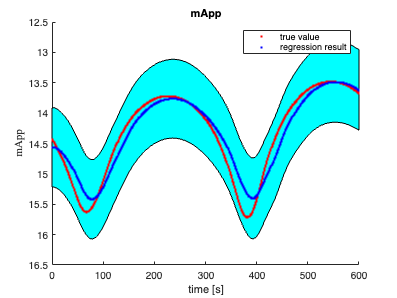

    if predictionStep == 1
        [t, x] = ode45(@(t, x)eomAttiOrb_h(t,x,const,earthVSOP,sat,jd), tstep_span, x_ode(i,:), options);
        x_ode(i+1,:) = x(end,:);
        x_reg(i+1,1:4) = x_ode(i+1,7:10); % [q]
        % x_reg(i+1,5:13) = x_reg(i,5:13); % [satPos, obsPos, sunPos]
        if strcmp(inputGP, "attitude, position, mApp_pastMean")

        % tstep_span後の位置情報が欲しい -----------
            x_reg(i+1,5:7) = x_ode(i+1,1:3) ./ r_valid_max; % [r]
    
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            x_reg(i+1,8:10) =  obsECI_tmp(end,:) ./ obsECI_valid_max; % [obsECI]
    
            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
            % x_reg(i+1,11:13) = sunPosI_tmp(end,:); % [sunPosI] % 一旦無視
        elseif strcmp(inputGP, "attitude, relativePosition, mApp_pastMean")
            jdHistory_tmp = jd + s2day(t);
            jd = jd + s2day(t(end)); % jd を更新 for next step
            [yy, mm, dd, hh, m, s] = jd2gc(jdHistory_tmp);
            utc_tmp = datetime([yy, mm, dd, hh, m, s]);
            for ii = 1:1:length(t)
                dcmITRF2gcrf_tmp = itrf2gcrf(utc_tmp(ii), leapJD, iau06, eopDataAll); % International Terrestrial Reference Frame to Geocentric Celestial Reference Frame(inertial frame)
                qITRF2gcrf_tmp(ii,:) = dcm2q(4, dcmITRF2gcrf_tmp);
            end
            obsECI_tmp = qRotation(4, repmat(obsPosECEF, length(jdHistory_tmp),1), qITRF2gcrf_tmp);
            
            x_reg(i+1, 5:7) = (x_ode(i+1, 1:3) - obsECI_tmp(end,:)) ./ obsToTarget_valid_max; % [r - obsECI]

            sunPosI_tmp = sun(jdHistory_tmp, const, earthVSOP);
            sunPosI_tmp = sunPosI_tmp .* 10^3; % [m]
        elseif strcmp(inputGP, "attitude, mApp_pastMean")
        elseif strcmp(inputGP, "attitude")
        end
    
        x_reg(i+1, inputDim) = (x_reg(i, inputDim) * tSpanPast + valid.mApp(i+1,1)) / (tSpanPast+1); % [mApp_pastMean], 観測値を使う．

- predictionStep == 2. input: x_reg(i, :), output: y_reg_mu(i, 2:end)

    elseif predictionStep == 2
        for j = 2:1:size(y_reg_mu, 2)
            [y_reg_mu(i+1,j), y_reg_var(i+1,j)] = gprNormal(x_reg(i,:), x_train(:,1:inputDim), y_train(:,j), params, Kinv_Dp); % input: 
        end
        y_reg_mu(i,2:end) = y_reg_mu(i,2:end) + y_train_mean(i,2:end);
        y_reg(i+1,2:5) = qMult_h(y_reg(i,2:5), rv2q(y_reg_mu(i,2:4)));
        y_reg(i+1,6:end) = y_reg(i,6:end) + y_reg_mu(i,5:end);
    end
end

- 最後にもう一回 observation step

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprNormal(x_reg(end, :), x_train(:,1:inputDim), y_train, params, Kinv_Do); % input: [q_k, satPos_k, obsPos_k, sunPos_k], output: [mApp_k]
y_reg(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); 
% y_reg(end,1) = y_reg_mu(end,1);

### export to csv

とりあえずしない

### plot

mkdir ../results/GP_static/
savedir = strcat(curdir, '/../results/GP_static/');

fignames = ["mApp"];
x_label = "time [s]";
y_labels = ["mApp"];

figure('Name', fignames(1));
plot_gpr(t_, y_reg(:,1), valid.mApp, y_reg_var(:,1), fignames(1), x_label, y_labels(1), savedir, 1);